% EE541 ANTENNA RADIATION PATTERN MEASUREMENT SYSTEM
% Facundo Soto-Wang

clear;
clc;
close all;

## SERIAL CONFIGURATION

PORT = "COM4";
BAUD = 115200;

device = serialport(PORT,BAUD);
device.Timeout = 60;

flush(device);

## USER PARAMETERS

NUM_SAMPLES = 2695;

ADC_MAX = 4095;
VREF = 3.3;

ALPHA = 0.075;      % Single-pole IIR LPF coefficient

BIAS_VOLTAGE = 1.44;

POWER_SCALE = 1;

## PACKET HEADERS

AZ_HDR1 = hex2dec('AAAA');
AZ_HDR2 = hex2dec('5555');

EL_HDR1 = hex2dec('AAAA');
EL_HDR2 = hex2dec('5555');

## ANGLE AXIS

angle_deg = (0:NUM_SAMPLES-1)' * (360/NUM_SAMPLES);

theta_rad = deg2rad(angle_deg);

## DATA TABLES

AzimuthTable = table( ...
    angle_deg,...
    zeros(NUM_SAMPLES,1),...
    zeros(NUM_SAMPLES,1),...
    zeros(NUM_SAMPLES,1),...
    'VariableNames',...
    {'Angle_deg','Voltage_V','Signal_V','Power'});

ElevationTable = table( ...
    angle_deg,...
    zeros(NUM_SAMPLES,1),...
    zeros(NUM_SAMPLES,1),...
    zeros(NUM_SAMPLES,1),...
    'VariableNames',...
    {'Angle_deg','Voltage_V','Signal_V','Power'});

## STARTUP MESSAGE

fprintf('\n');
fprintf('===============================================\n');

fprintf(' EE541 ANTENNA PATTERN MEASUREMENT SYSTEM\n');

 EE541 ANTENNA PATTERN MEASUREMENT SYSTEM


fprintf('===============================================\n');

fprintf(' Waiting for Azimuth Packet...\n\n');

 Waiting for Azimuth Packet...



## GUI

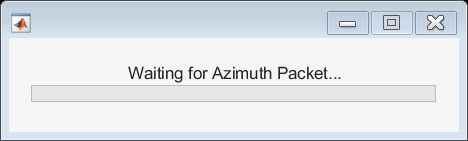

hWait = waitbar(0,'Waiting for Azimuth Packet...');

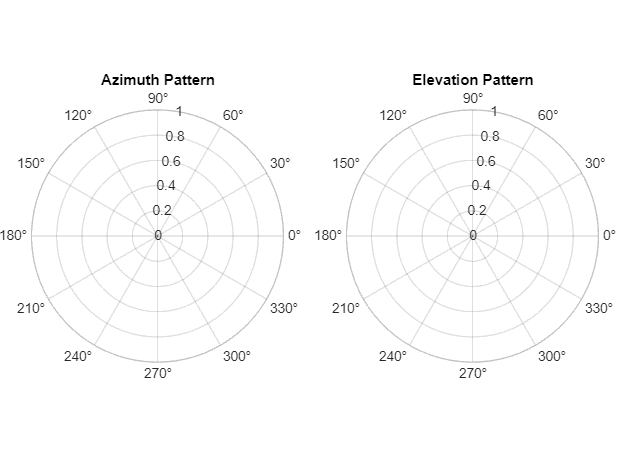


figure('Name','EE541 Radiation Pattern Measurement',...
    'NumberTitle','off');

axAz = polaraxes('Position',[0.05 0.10 0.40 0.80]);
title(axAz,'Azimuth Pattern');

axEl = polaraxes('Position',[0.55 0.10 0.40 0.80]);
title(axEl,'Elevation Pattern');


drawnow;

## WAIT FOR AZIMUTH HEADER

WaitForHeader(device,AZ_HDR1,AZ_HDR2);


fprintf('Azimuth Packet Detected\n');

Azimuth Packet Detected


## AZIMUTH ACQUISITION

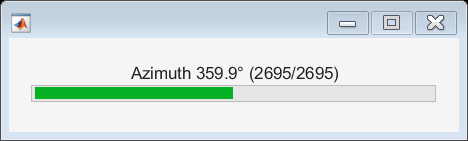

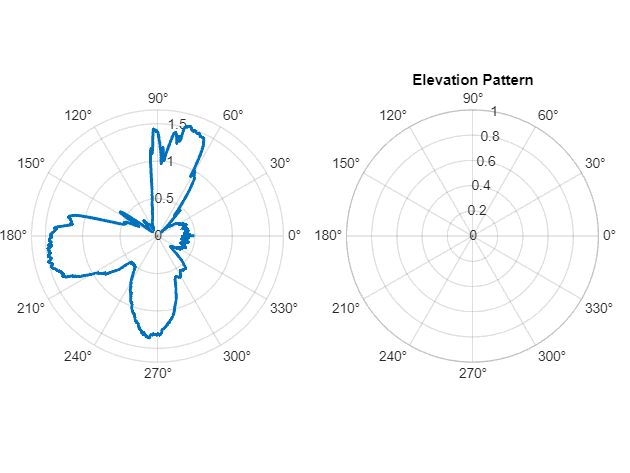

azFilteredPower = 0;

for k = 1:NUM_SAMPLES
    
    adcValue = read(device,1,"uint16");
    
    voltage = double(adcValue) * VREF / ADC_MAX;
    
    signalVoltage = max(voltage - BIAS_VOLTAGE,0);
    
    power = signalVoltage * POWER_SCALE;

    if k == 1
        azFilteredPower = power;
    else
        azFilteredPower =ALPHA * power + (1-ALPHA) * azFilteredPower;
    end

AzimuthTable.Voltage_V(k) = voltage;
AzimuthTable.Signal_V(k) = signalVoltage;
AzimuthTable.Power(k) = azFilteredPower;
    
    if mod(k,5)==0 || k==NUM_SAMPLES
        
        polarplot(axAz,...
            theta_rad(1:k),...
            AzimuthTable.Power(1:k),...
            'LineWidth',2);
        
        maxPower = max(AzimuthTable.Power(1:k));
        
        if maxPower > 0
            rlim(axAz,[0 maxPower*1.1]);
        end
        
        drawnow limitrate;
        
    end
    
    waitbar(0.5*(k/NUM_SAMPLES),...
        hWait,...
        sprintf('Azimuth %.1f° (%d/%d)',...
        angle_deg(k),...
        k,...
        NUM_SAMPLES));
    
end


fprintf('Azimuth Sweep Complete\n');

Azimuth Sweep Complete


## WAIT FOR ELEVATION HEADER

fprintf('Waiting for Elevation Packet...\n');

Waiting for Elevation Packet...



WaitForHeader(device,EL_HDR1,EL_HDR2);

fprintf('Elevation Packet Detected\n');

Elevation Packet Detected


## ELEVATION ACQUISITION

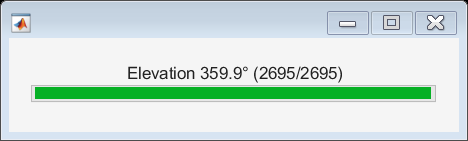

elFilteredPower = 0;

for k = 1:NUM_SAMPLES
    
    
    adcValue = read(device,1,"uint16");
    
    voltage = double(adcValue) * VREF / ADC_MAX;
    
    signalVoltage = max(voltage - BIAS_VOLTAGE,0);
    
    power = signalVoltage * POWER_SCALE;

    if k == 1
        elFilteredPower = power;
    else
        elFilteredPower = ALPHA * power + (1-ALPHA) * elFilteredPower;
    end

ElevationTable.Voltage_V(k) = voltage;
ElevationTable.Signal_V(k) = signalVoltage;
ElevationTable.Power(k) = elFilteredPower;
    
    if mod(k,5)==0 || k==NUM_SAMPLES
        
        polarplot(axEl,...
            theta_rad(1:k),...
            ElevationTable.Power(1:k),...
            'LineWidth',2);
        
        maxPower = max(ElevationTable.Power(1:k));
        
        if maxPower > 0
            rlim(axEl,[0 maxPower*1.1]);
        end
        
        drawnow limitrate;
        
    end
    
    waitbar(0.5 + 0.5*(k/NUM_SAMPLES),...
        hWait,...
        sprintf('Elevation %.1f° (%d/%d)',...
        angle_deg(k),...
        k,...
        NUM_SAMPLES));
    
    
end


fprintf('Elevation Sweep Complete\n');

Elevation Sweep Complete


## FINISH

waitbar(1,hWait,'Processing Complete');
pause(1);
close(hWait);

## PEAK REPORT

[maxAzPower,maxAzIdx] = max(AzimuthTable.Power);

[maxElPower,maxElIdx] = max(ElevationTable.Power);

fprintf('\n');
fprintf('Azimuth Peak:\n');

Azimuth Peak:


fprintf('  Power = %.4f\n',maxAzPower);

  Power = 1.5313


fprintf('  Angle = %.2f deg\n',angle_deg(maxAzIdx));

  Angle = 73.60 deg



fprintf('\n');
fprintf('Elevation Peak:\n');

Elevation Peak:


fprintf('  Power = %.4f\n',maxElPower);

  Power = 0.7113


fprintf('  Angle = %.2f deg\n',angle_deg(maxElIdx));

  Angle = 278.12 deg


## COMBINED POLAR PLOT

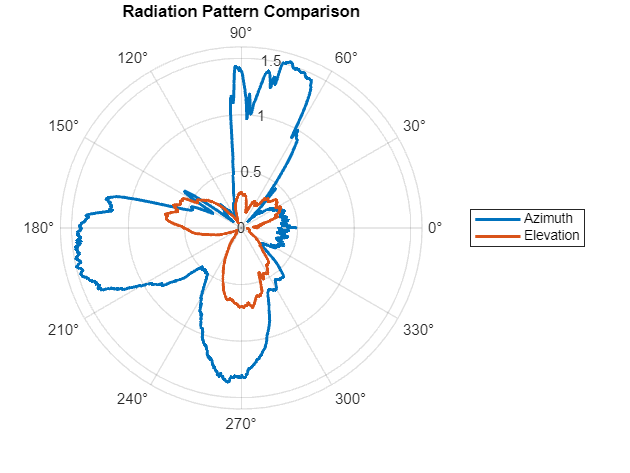

figure('Name','Radiation Pattern Comparison');

polarplot(theta_rad,...
    AzimuthTable.Power,...
    'LineWidth',2);

hold on;

polarplot(theta_rad,...
    ElevationTable.Power,...
    'LineWidth',2);

legend('Azimuth','Elevation');

title('Radiation Pattern Comparison');

exportgraphics(gcf,...
    'radiation_pattern_comparison.png',...
    'Resolution',300);

savefig('radiation_pattern_comparison.fig');

## 3D APPROXIMATION

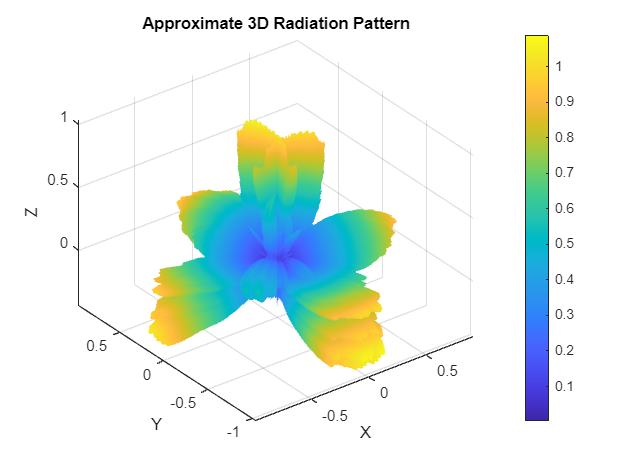

[AZ,EL] = meshgrid(theta_rad,theta_rad);

R = AzimuthTable.Power * ElevationTable.Power';

[X,Y,Z] = sph2cart(AZ,EL-pi/2,R);

figure('Name','Approximate 3D Radiation Pattern');

surf(X,Y,Z,R);

shading interp;
axis equal;

xlabel('X');
ylabel('Y');
zlabel('Z');

title('Approximate 3D Radiation Pattern');

colorbar;

exportgraphics(gcf,...
    'radiation_pattern_3d.png',...
    'Resolution',300);


savefig('radiation_pattern_3d.fig');

## PEAK SUMMARY

PeakSummary = table( ...
    maxAzPower,...
    angle_deg(maxAzIdx),...
    maxElPower,...
    angle_deg(maxElIdx),...
    'VariableNames',...
    {'AzimuthPeakPower',...
    'AzimuthPeakAngle',...
    'ElevationPeakPower',...
    'ElevationPeakAngle'});

## SAVE DATA

writetable(AzimuthTable,...
    'azimuth_pattern.csv');

writetable(ElevationTable,...
    'elevation_pattern.csv');

writetable(PeakSummary,...
    'peak_summary.csv');

## CLEANUP

clear device;

## ============================================================

## LOCAL FUNCTION

## ============================================================

function WaitForHeader(device,hdr1,hdr2)

while true
    
    
    word1 = read(device,1,"uint16");
    
    if word1 == hdr1
        
        word2 = read(device,1,"uint16");
        
        if word2 == hdr2
            return;
        end
        
    end
    
end

end